clear all
load total_biomass.txt
load CO2VsMeintenance.txt

x = categorical(["0" "4" "8" "16"]);
x = reordercats(x,{'0' '4' '8' '16'});
nil = [0; 0; 0; 0;];
%ybio=total_biomass(:,2)
%bar(ybio)
%hold on
barchart(1,:)=transpose(CO2VsMeintenance(:,2))

barchart =     0.0614    0.1008    0.1132    0.1221


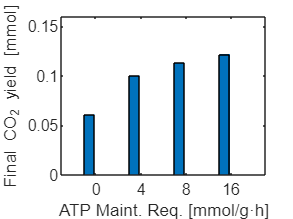

hBar=bar(x,[transpose(barchart) nil],'grouped');
%set(gca,'YScale','log')
ylim([0 0.16])
xlabel('ATP Maint. Req. [mmol/g·h]')
ylabel('Final CO_2 yield [mmol]')
%legend('CO_2','Formate','Acetate')
hold on

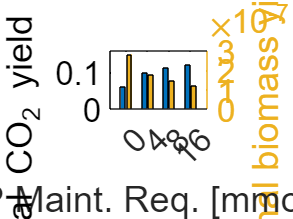

ax =   Axes with properties:

    YAxisLocation: 'right'
            YAxis: [2×1 NumericRuler]
             YLim: [0 3.0000e-07]
             XLim: [0    16]
           XScale: 'linear'
           YScale: 'linear'
         Position: [0.1776 0.1557 0.6898 0.7540]
            Units: 'normalized'

  Show all properties



yyaxis right
ylabel('Final biomass yield [g]')
bBar=bar(x,[nil total_biomass(:,2)],'grouped');
%set(bBar,'FaceColor','red');
%set(bBar,'Color','red')
%legend('CO_2','Biomass')
ax=gca;
ax.FontSize=18

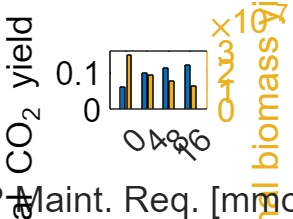

exportgraphics(gcf,'CO2Biomass.png','Resolution', 300)